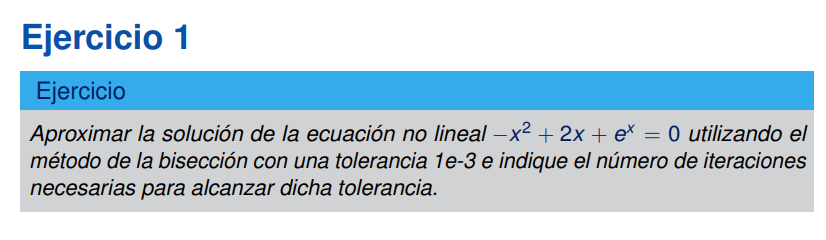

f = @(x) -x.^2 + 2*x + exp(x);

a = -1;
b = 0;
Tol = 1e-3;

i = 0;

while (b-a)/2 > Tol

    c = (a+b)/2;

    fprintf('%d   %.6f   %.6f   %.6f   %.6f\n',...
        i,a,b,c,f(c))

    if f(a)*f(c) < 0
        b = c;
    else
        a = c;
    end

    i = i + 1;

end

0   -1.000000   0.000000   -0.500000   -0.643469
1   -0.500000   0.000000   -0.250000   0.216301
2   -0.500000   -0.250000   -0.375000   -0.203336
3   -0.375000   -0.250000   -0.312500   0.008959
4   -0.375000   -0.312500   -0.343750   -0.096558
5   -0.343750   -0.312500   -0.328125   -0.043643
6   -0.328125   -0.312500   -0.320312   -0.017303
7   -0.320312   -0.312500   -0.316406   -0.004162
8   -0.316406   -0.312500   -0.314453   0.002401



c = (a+b)/2;

fprintf('\nRaiz aproximada = %.6f\n',c)


Raiz aproximada = -0.315430


fprintf('Numero de iteraciones = %d\n',i)

Numero de iteraciones = 9


fprintf('Error maximo = %.6f\n',(b-a)/2)

Error maximo = 0.000977
